# Atividade 02_02

Otávio Baziewicz Filho - 1942808

## **Script**

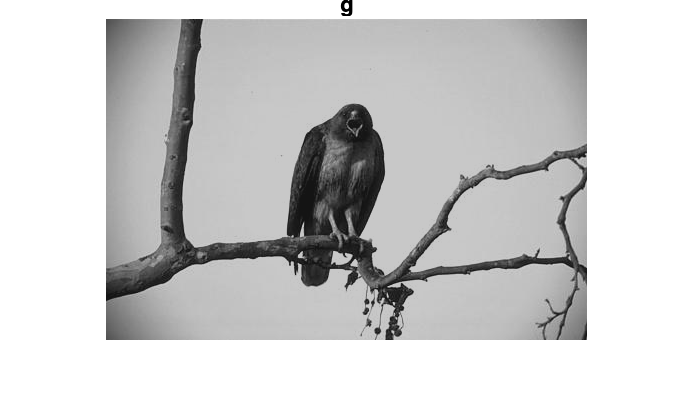

% aipt_02 [script]
clear all; close all; clc
g=imread('42049_20-200.png');
mg=min(g(:));
Mg=max(g(:));
figure, imshow(g), title('g')

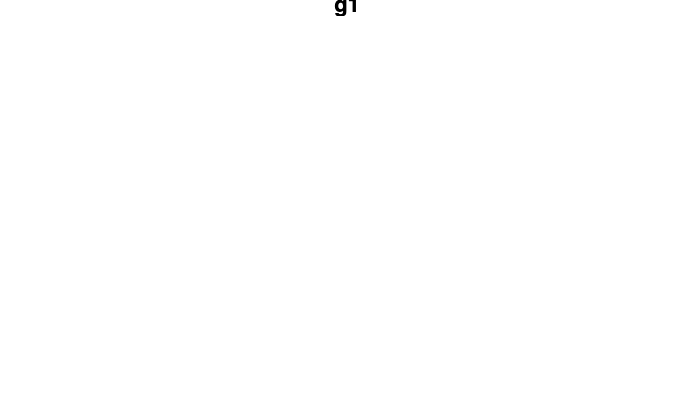


g1=double(g);
mg1=min(g1(:));
Mg1=max(g1(:));
figure, imshow(g1); title('g1')

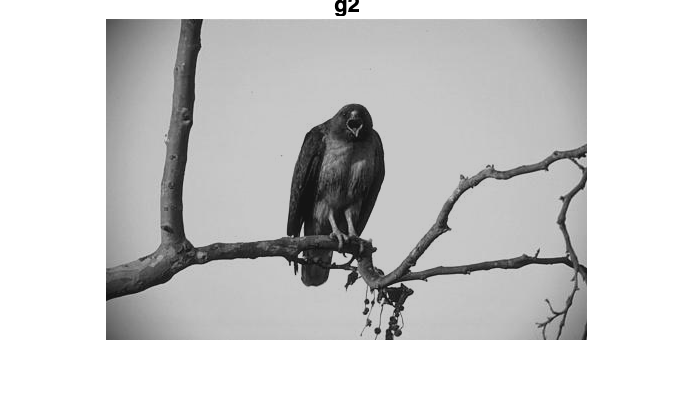


g2=im2double(g);
mg2=min(g2(:));
Mg2=max(g2(:));
figure, imshow(g2), title('g2')

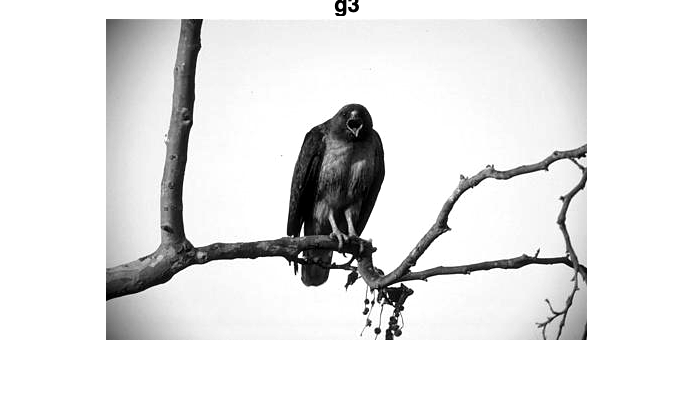


g3=mat2gray(g);
mg3=min(g3(:));
Mg3=max(g3(:));
figure, imshow(g3), title('g3')

## Questões

g é da classe: **uint8**

Mín em g: **20**, Máx em g: **200**

g1 é da classe: **double**

Mín. em g1: **20**, Máx em g1: **200**

imshow(g1) mostra uma imagem: **Não exatamente. Uma imagem branca.**

porque: **A image g1 é da classe double, e o intervalo esperado dessa classe é [0, 1]. O resultado da conversão de uint8 resultou em valores no intervalo [20, 200], fazendo com que todos os pixels fossem saturados.**

g2 é da classe: **double**

Mín em g2: **0.0784**, Máx em g2: **0.7843**

g3 é da classe: **double**

Mín em g3: **0**, Máx em g3: **1**

Qual é a diferença entre as funções im2double e mat2gray? **A função im2double converte a classe da imagem para double fazendo uma conversão de intervalo para [0, 1]. Já a função mat2gray converte a imagem para grayscale, e quando usada sem os argumentos de amin e amax, a função faz um autocontrast usando o mínimo e o máximo da imagem.**